## 介绍

这是一个能直接给出常见聚变反应的反应截面和反应率系数的MATLAB数据包。

要使用，载入该数据包（**注意！需要安装Curve Fitting Toolbox才能正确运行**）

clear;
Load_Xsec_and_reactiv; % 载入截面和反应率的拟合式

这个数据包是将包含了以下几种常见反应

types'

ans = 5×1 string 数组
    "D_T"
    "D_D"
    "D_He3"
    "T_He3"
    "T_T"


的反应截面和反应率的数据，是两个struct：

Xsec_fit;
reactiv_fit;

数据根据实测数据已经通过插值整理好，只要圆点到反应类型，给进一个能量/温度，就能得到对应的反应截面和反应率。注意事项：

- 质心系动能/温度的单位为**keV**，截面的单位为**b**，反应率的单位为**SI**。

- 反应截面的能量范围为10.^[0,4]，反应率的温度范围为10.^[0,3.5]。

- 输入限定为**列向量**。

## 简单例子

例如，要取D-T反应在65 keV的反应截面，只需输入：

Xsec=Xsec_fit.D_T(65)

Xsec = 5.0140

可见，得到了反应截面为5.01 b的结果。

要取D-He3反应在233 keV的反应率系数，只需输入：

myType="D_He3";
myT=233;
reactiv=reactiv_fit.(myType)(myT)

reactiv = 2.6217e-22

可见，得到了反应率系数为2.62e-22的结果。

要注意的是，由于field名的命名规则所限，名称是用的下划线「D_T」而不是连接线「D-T」。

而如果要取一大串质心系动能E值下的反应截面，只需将输入E换成相应的E**列向量**：

E_data=10.^[1:0.1:3]'; %列向量
Xsec_data=Xsec_fit.D_T(E_data);

便得到了与温度对应的反应截面的值，可以绘图了：

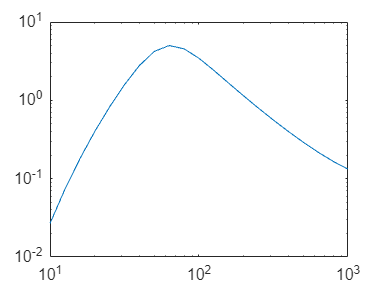

loglog(E_data,Xsec_data)

由于反应截面的特质，往往选用对数坐标绘图更为方便。

## 综合例子

画出这几种反应的反应截面图

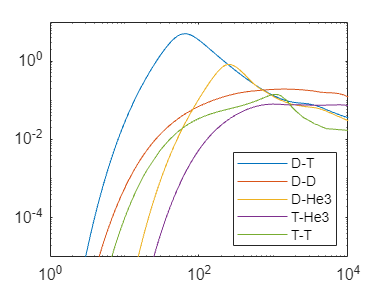

E_data=10.^[0:0.01:4]'; %列向量
for type=types
	Xsec_data=Xsec_fit.(type)(E_data);
	loglog(E_data,Xsec_data);hold on
end
hold off
axis(10.^[0,4,-5,1])
legend(replace(types,'_','-'),'Location','southeast')

作业上画出这种程度的图就very nice了！怎么样，是不是很简单？如果想再精益求精一点的话，还可以添加坐标轴标签、加上网格、修改字体等等。

虽然为了使用方便，反应率的数据已经计算好了，但是反应率的计算实际也是非常简单的。比如说要计算双热平衡分布，T=233 keV时D-He3的反应率：

T=233;
E_data=10.^[0:0.01:4]'; %列向量
Xsec_data=Xsec_fit.D_He3(E_data);

T1=T.*1.6e-16; %转回公制
E_data1=E_data.*1.6e-16;
Xsec_data1=Xsec_data.*1e-28;
m_r=1/(1/2+1/3)*1.66E-27;
cache=E_data1.*Xsec_data1; % 提前计算，节约时间

% trapz离散积分
mycalc=sqrt(8/pi/m_r)/T1^1.5*trapz(E_data1,cache.*exp(-E_data1/T1))

mycalc = 2.6300e-22

诶……跟记载的插值值差了一丁点，但还是符合得很好的！